## Example 1: Fitting a noisy Gamma PDF

In general you might want to fit EEG data (epochs) directly, using `gmaFitEeg` (see other examples). 

To demonstrate the usage for an arbitrary data vector, we fit a generated "ideal" Gamma PDF, smudged by random noise and plots the results.

Only the basic parameters will be demonstrated here, others can be found in the documentation; see `help gmaFit`.

% Basic parameters for the original Gamma PDF in shape and rate format
% and the number of data points for the source PDF.
tshape = 20;
trate = 0.5;
n = 100;

% Ideal PDF
idealPdf = GammaDist(tshape, trate, 100, 1:n);

% Add some noise (as a factor 0..)
noiseLevel = 1.5;
rng(12345);
noisyData = idealPdf.y + (noiseLevel * (rand(1,n) - 0.5));

% Create the signal and provide a name (used in the plot)
testSignal.data = noisyData;

% By default, the sampling rate is 1000 Hz and the first data point is time zero. 
% For demonstration purposes, we change the values and add a title, which will be
% used by the plotting function:
testSignal.srate = 500;
testSignal.xmin = -0.020;
testSignal.setname = sprintf('Gamma PDF with noise s=%.2f, r=%.2f with random noise', tshape, trate);

% Set the search window for the GMA (in data points):
% The mode must be inside for a successful fit.
winStart = 21;
winLength = 50;

% Run the GMA (logging can be disabled)
tic; gResults = gmaFit(testSignal.data, winStart, winLength, logEnabled = true); t1 = toc;

Gamma Model Analysis - Started
Nonnegative interval found at [16, 63].
Data segment padded by [15, 0]
Start - Pre-Search
Start - GRNMA Optimization
Initial guess: shape=17.2438, rate=0.44067, yscale=109.436
Logger initialized

Start GRNMA optimization
Optimization successful. Optimization criteria satisfied.
Iterations: 397/3000 cost function, 166/1000 algorithm.
GRNMA exit flag: 1, iterations: 166



Successful GMA fit of mode inside search window between [21, 71] samples.
shape=18.734	rate=0.470	yscale=102.039
skewness=0.462	excess=0.320
ip1=28.786	mode=37.750	ip2=46.715	
rmse=0.4149	nrmse=0.2674	r=0.9639


### Plotting

The provided plotting function (`plotGmaResults`) serves as a demonstration how to use the resulting instance of `GmaResults` in code. We can use it to take a first glance at the results. 

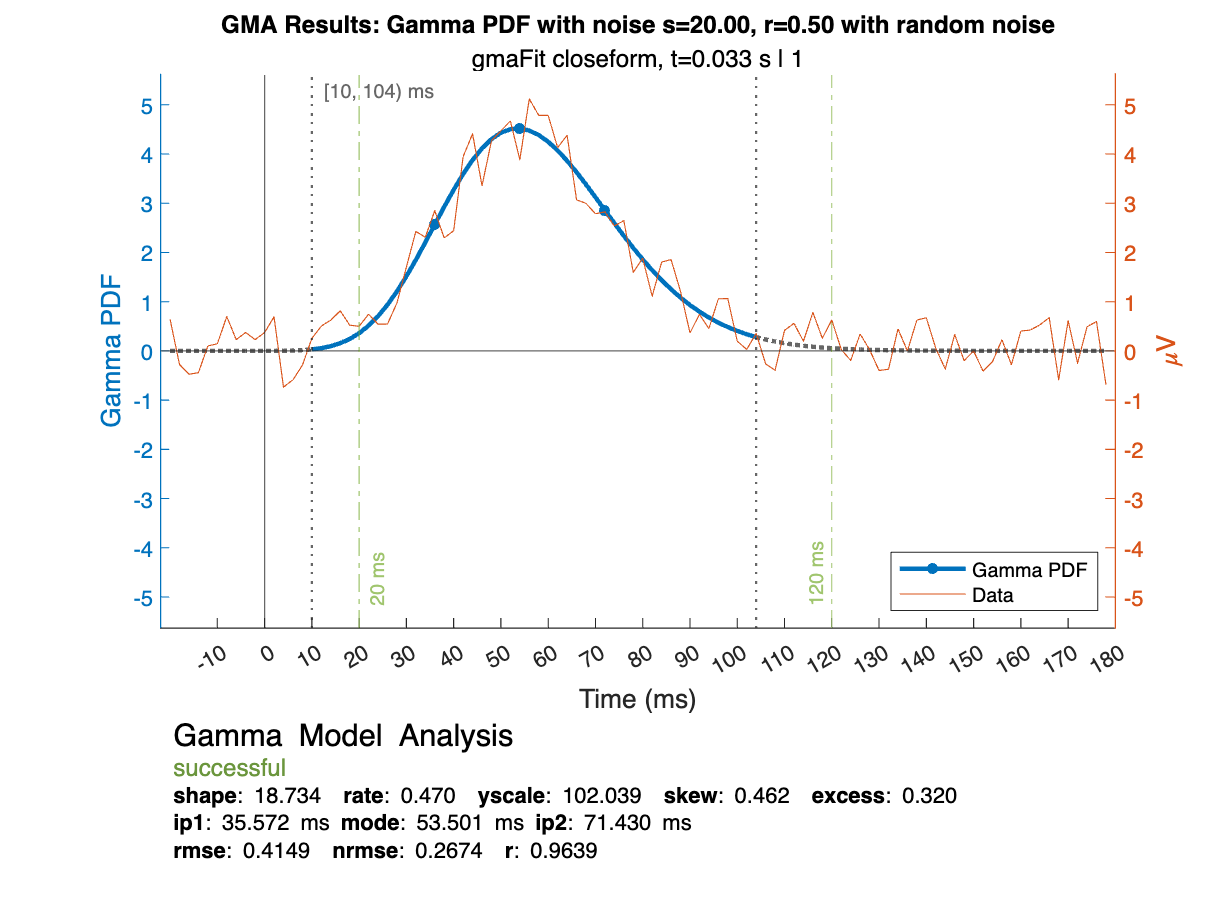

% Add add information about the signal.
% Can be used to extract settings from EEG data. 
% Here, we only set a channel to be displayed in the plot.
gResults.addEegInfo(testSignal, 1);
plotGmaResults(gResults, desc = sprintf('gmaFit closeform, t=%.3f s', t1), ticksMs = 10);

The resulting plot displays the data and the GMA fitted PDF above the data, together with the search window for the mode (green) and the detected nonnegative interval (dotted line) which was used for the fit.

### Compare the fit to the ideal PDF with the fit

Depending on the level of noise, the fit should still be very close to the original Gamma PDF.

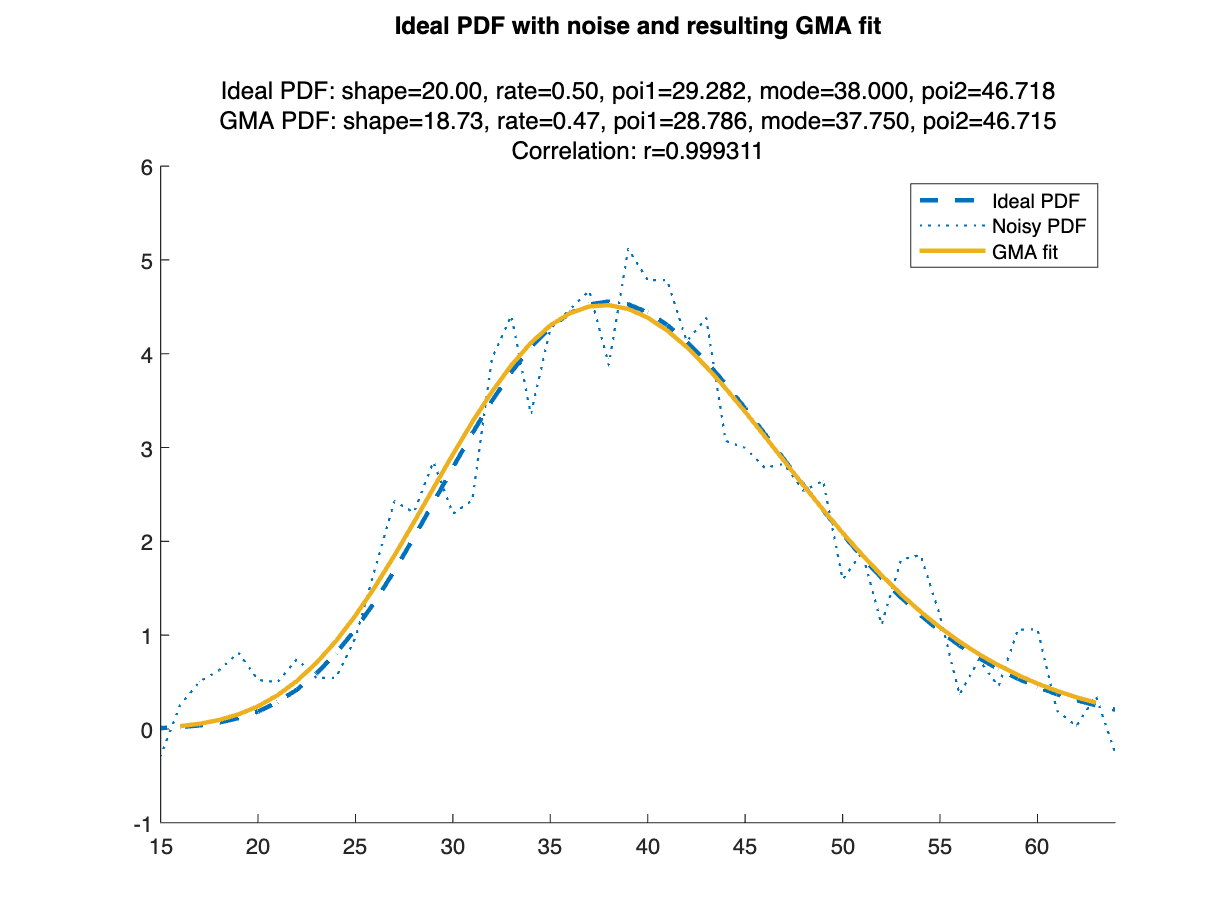

% Correlation
ds = gResults.seg(1):gResults.seg(2);
rmat = corrcoef(gResults.y, idealPdf.y(ds), Rows = "complete");
r = rmat(1, 2);

% Plot
cColors = colororder;

figure;
hold on
plot(idealPdf.y, LineStyle = "--", LineWidth = 2, Color=[cColors(1, :), 1], DisplayName="Ideal PDF");
plot(noisyData, LineStyle = ":", LineWidth = 1, Color=[cColors(1, :), 1], DisplayName="Noisy PDF");
plot(gResults.x, gResults.y, LineStyle = "-", LineWidth = 2, Color=[cColors(3, :), 1], DisplayName="GMA fit");
title(['Ideal PDF with noise and resulting GMA fit', newline]);
subtitle({sprintf('Ideal PDF: shape=%.2f, rate=%.2f, poi1=%.3f, mode=%.3f, poi2=%.3f', ...
    tshape, trate, idealPdf.ip1, idealPdf.mode, idealPdf.ip2), ...
    sprintf('GMA PDF: shape=%.2f, rate=%.2f, poi1=%.3f, mode=%.3f, poi2=%.3f', ...
    gResults.shape, gResults.rate, gResults.ip1, gResults.mode, gResults.ip2), ...
    sprintf("Correlation: r=%f", r)})

xlim(gResults.seg + [-1, 1]);
legend();
hold off